# Interpolació inversa

## Aprenem....

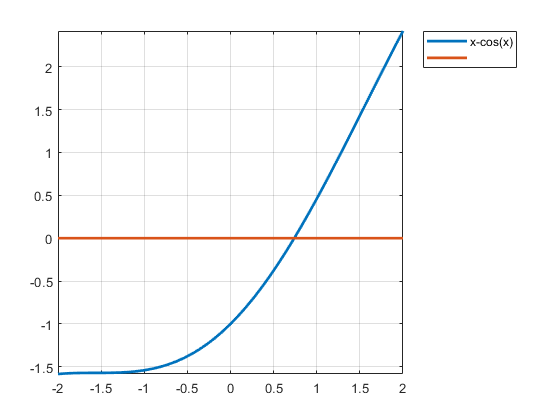

f=@(x)x-cos(x); 
fplot({f,0},[-2,2],'LineWidth',2),grid,legend('Location','bestoutside')

raiz = fzero(f,1)

raiz =       0.73909


xnodes=[-0.5:0.25:1.5];
ynodes=f(xnodes);
disp([xnodes;ynodes])

  Columns 1 through 6

         -0.5        -0.25            0         0.25          0.5         0.75
      -1.3776      -1.2189           -1     -0.71891     -0.37758     0.018311

  Columns 7 through 9

            1         1.25          1.5
       0.4597      0.93468       1.4293



alpha = polyinterp(ynodes,xnodes,0)

alpha =       0.73903


comparacio = abs(alpha-raiz)

comparacio =    5.9519e-05
